load('EFRET_vector.mat');
x=EFRET;

Below we're checking for the density of time points; the non-time-normalized histogramming 

method does not work in regions where this density isn't flat...

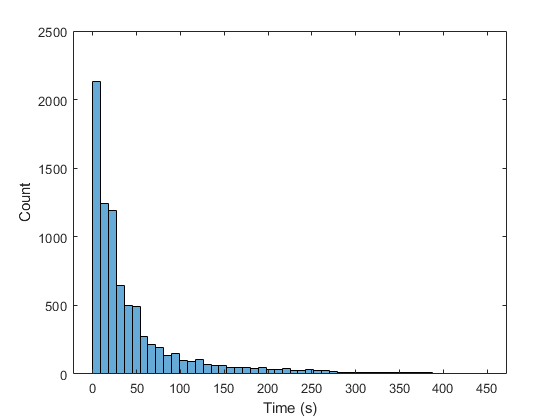

histogram(x(:,1),50)
xlabel('Time (s)')
ylabel('Count')

% sel = (x(:, 1) < 85) & (x(:, 2) > 0.1);
% x = x(sel, :);
% histogram(x(:,1),50)
% xlabel('Time (s)')
% ylabel('Count')

% change settings below as needed
gridx1 = 0:2.67:100; % graph pixel time axis coordinates
gridx2 = 0:0.005:1; % graph pixel Efret coordinates
cellarea = 2.67 * 0.005; % product of the two middle numbers above
bw = [5, 0.05]; % bandwith: the s.d. of the Gaussian kernel along each axis

% make negative image of data within 3 sigma of t=0
ttol = 3 * bw(1);
xim=x(x(:,1)<ttol & x(:,1)>0,:);
xim(:,1)=xim(:,1).* -1;
x = [x;xim];
[f, intgl, x1s, x2s]=kernel_hist_2d(x,gridx1,gridx2,bw,cellarea);
intgl

intgl = 0.6392

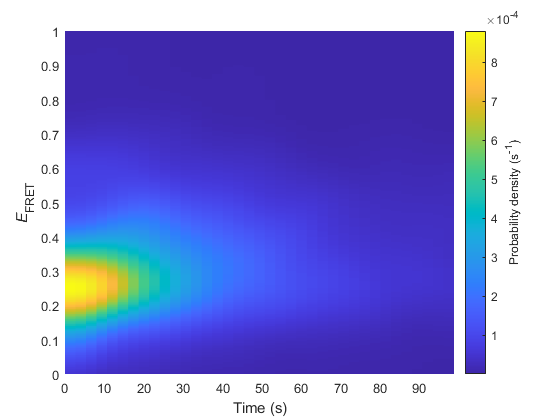

h=fret_hist_2d(x1s,x2s,f);
c=colorbar;
c.Label.String='Probability density (s^-^1)';

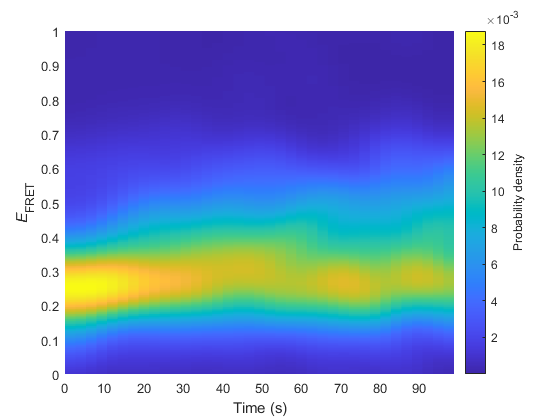

% renormalize so that integral is the same at each time
renor = sum(f,2);
f_norm = f ./ (renor * ones(1, length(gridx2)));
%sum(f_norm, 2)
h=fret_hist_2d(x1s,x2s,f_norm);